Output of equalizer and noise filter

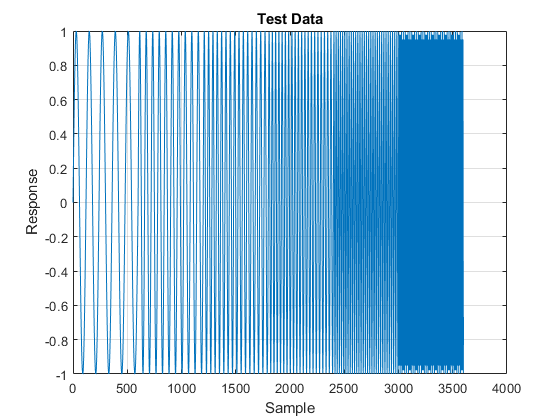

fileName = 'Equalizer and Noise Filter Output';
load(fullfile(pwd, fileName));
sample = outData(:,1);
test_vector = outData(:,2);

figure
% hold on
plot(sample, test_vector)
grid on
title('Test Data')
xlabel('Sample')
ylabel('Response')

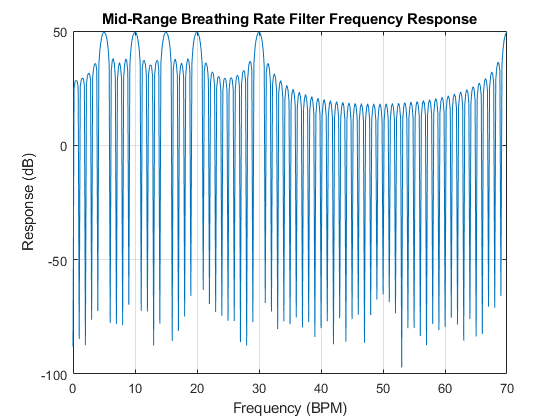


% Frequency Response
FFT_response = fft(test_vector, 3600);
response_dB = 20*log10(abs(FFT_response));
breathing_rate = [0:3599]/3599 * 10 * 60;

figure
plot(breathing_rate, response_dB)
grid on
title('Mid-Range Breathing Rate Filter Frequency Response')
xlabel('Frequency (BPM)')
ylabel('Response (dB)')
xlim([0,70])

Output of noise filter

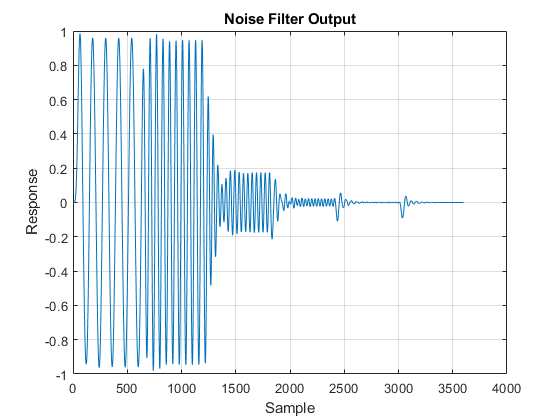

fileName = 'low_filter_large.mat';
load(fullfile(pwd, fileName));
sample = outData(:,1);
output = outData(:,3);

figure
% hold on
plot(sample, output)
grid on
title('Noise Filter Output')
xlabel('Sample')
ylabel('Response')

Output of low rate filter

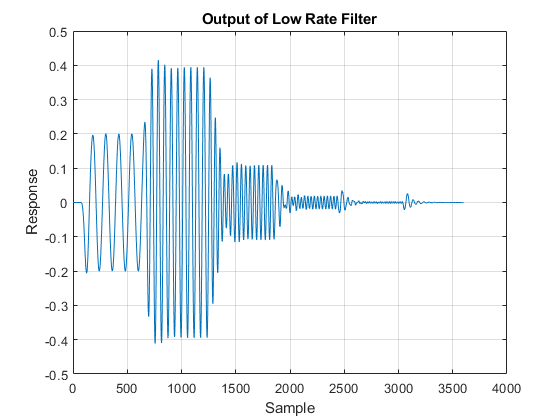

fileName = '3 Parallel Rate Filter Outputs';
load(fullfile(pwd, fileName));
sample = outData(:,1);
output = outData(:,3);
stdLow = outData(:,6);

figure
plot(sample, output)
grid on
title('Output of Low Rate Filter')
xlabel('Sample')
ylabel('Response')

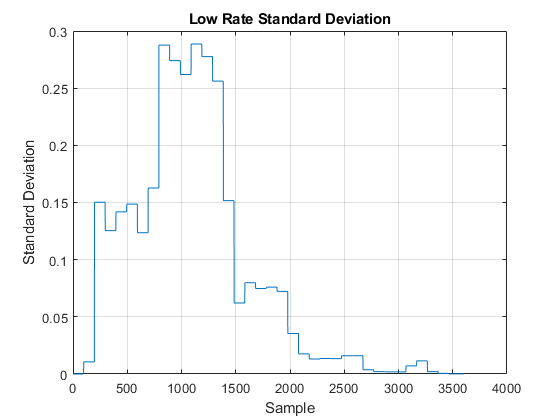


plot(sample, stdLow)
grid on
title('Low Rate Standard Deviation')
xlabel('Sample')
ylabel('Standard Deviation')

Output of mid rate filter

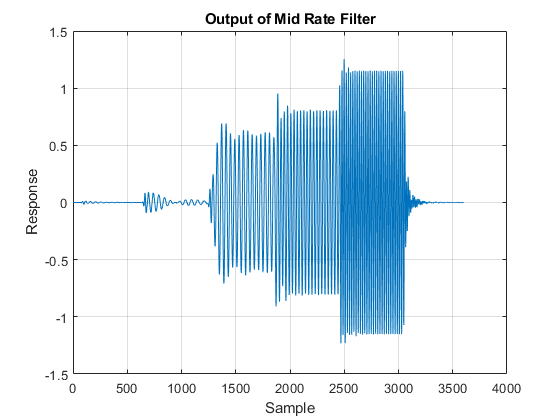

fileName = '3 Parallel Rate Filter Outputs';
load(fullfile(pwd, fileName));
sample = outData(:,1);
output = outData(:,4);
stdMid = outData(:,7);

figure
plot(sample, output)
grid on
title('Output of Mid Rate Filter')
xlabel('Sample')
ylabel('Response')

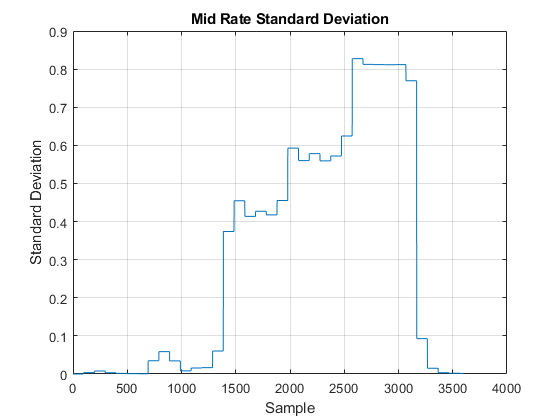


plot(sample, stdMid)
grid on
title('Mid Rate Standard Deviation')
xlabel('Sample')
ylabel('Standard Deviation')

Output of high rate filter

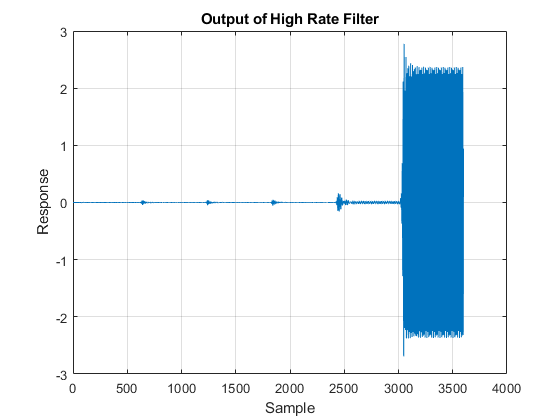

fileName = '3 Parallel Rate Filter Outputs';
load(fullfile(pwd, fileName));
sample = outData(:,1);
output = outData(:,5);
stdHigh = outData(:,8);

figure
plot(sample, output)
grid on
title('Output of High Rate Filter')
xlabel('Sample')
ylabel('Response')

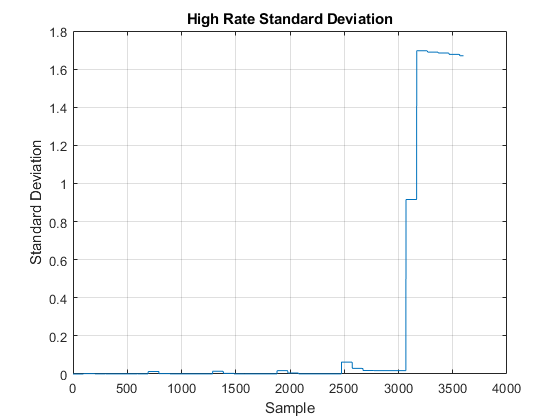


plot(sample, stdHigh)
grid on
title('High Rate Standard Deviation')
xlabel('Sample')
ylabel('Standard Deviation')